# `Beamforming ULA spectral estimation`

`First, simulate signals`

d = 0.5; % Element spacing
numElements = 4;
ula = phased.ULA('NumElements',numElements,'ElementSpacing',d);

ang1 = [40; 0];          % First signal
ang2 = [-20; 0];         % Second signal
angs = [ang1 ang2];

c = physconst('LightSpeed');
fc = 2.44e9;              % Operating frequency
lambda = c/fc;
pos = getElementPosition(ula)/lambda;

Nsamp = 1000;

nPower = 0.01; % thermal noise [W] at each antenna

rs = rng(2007); % random number generator
signal = sensorsig(pos,Nsamp,angs,nPower); % signal of interest (SOI)

Calculate covariance matrix

R = (signal' * signal)/Nsamp;

Calculate spectrum of MVDR beamformer

There are two ways: one which calculates the weighted steering vector, $\omega$, and uses that to estimate power.

The other calculates power directly which will be more efficient if you are not interested in the weighted steering vector.

theta_scan = -90:1:90;   % Range of angles to scan
sz_sig = [length(theta_scan) height(signal)]; % theta_scan x snapshot
sig_mvdr = zeros(sz_sig);
sig_cbf = zeros(sz_sig);
P_mvdr2 = zeros(size(theta_scan));  % Initialize power vector

n = transpose(0:numElements-1); % [0, 1, 2, ..., numElements-1]

for i = 1:length(theta_scan)
    ang = [theta_scan(i)];  % Current scan angle
    % steering_vector = phased.SteeringVector('SensorArray',ula,'PropagationSpeed',c);
    % a = steering_vector(fc, -ang);
    a = exp(-1j * 2 * pi * (d/lambda) * n * sin(deg2rad(ang)));
    w = inv(R) * (a / (a' * inv(R) * a));
    sig_mvdr(i,1:Nsamp) = signal * w;
    sig_cbf(i,1:Nsamp) = signal * a;
    P_mvdr2(i) = 1 / (a' * inv(R) * a);  % MVDR spectral power
end
P_mvdr = mean(abs(sig_mvdr).^2, 2);
P_cbf = mean(abs(sig_cbf).^2, 2);

Plot signals

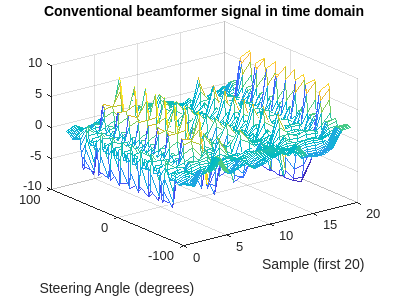

figure;
plotsamps = min(Nsamp, 20);
[x, y] = meshgrid(1:plotsamps, theta_scan);
mesh(x, y, real(sig_cbf(1:length(theta_scan), 1:plotsamps)));
ylabel('Steering Angle (degrees)');
xlabel('Sample (first 20)');
title('Conventional beamformer signal in time domain');

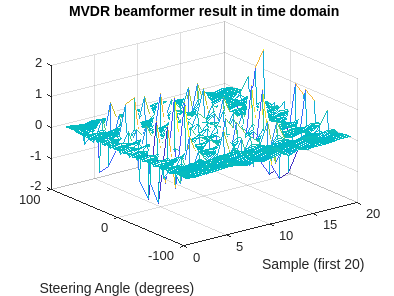

mesh(x, y, real(sig_mvdr(1:length(theta_scan), 1:plotsamps)));
ylabel('Steering Angle (degrees)');
xlabel('Sample (first 20)');
title('MVDR beamformer result in time domain');
grid on;

Normalize spectrum

P_mvdr = P_mvdr/max(P_mvdr);
P_mvdr2 = P_mvdr2/max(P_mvdr2);
P_cbf = P_cbf/max(P_cbf);

Plot results

figure;
plot(theta_scan, 10*log10(P_cbf), '-', 'LineWidth', 2);  % Convert power to dB
hold on;
plot(theta_scan, 10*log10(P_mvdr), '-', 'LineWidth', 2);  % Convert power to dB
hold on;
plot(theta_scan, 10*log10(P_mvdr2), '--', 'LineWidth', 2);  % Convert power to dB

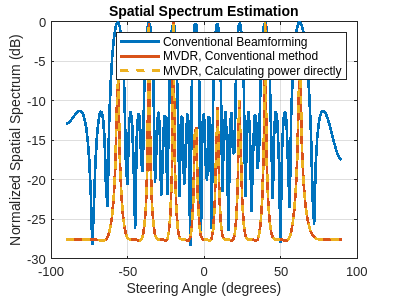

hold off;
legend('Conventional Beamforming', 'MVDR, Conventional method', 'MVDR, Calculating power directly');  % Add a legend
xlabel('Steering Angle (degrees)');
ylabel('Normalized Spatial Spectrum (dB)');
title('Spatial Spectrum Estimation');
grid on;